## **Primer Punto**

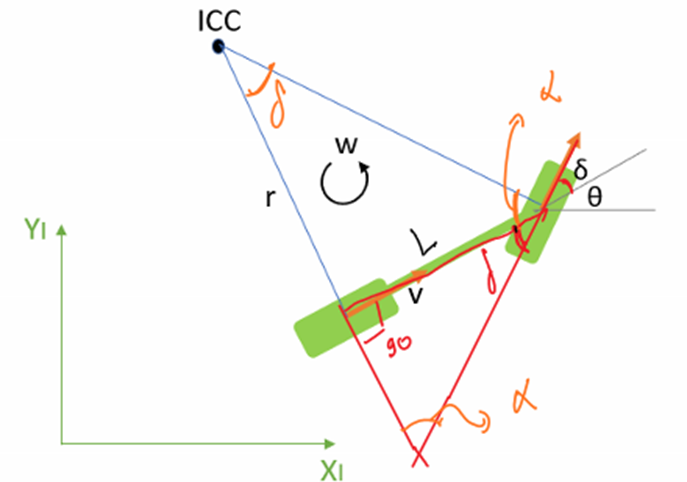

En la anterior figura se muestra la definición de los angulos y las diferentes variables necesarias, a continuación se demuestra las ecuaciones mencioanadas en la guia, primero se encuentran las variables mediante la matriz de rotación:

$\left\lbrack \begin{array}{c}
\dot{x^I } \\
\dot{y^I } \\
\dot{\theta^I } 
\end{array}\right\rbrack$= $\left\lbrack \begin{array}{ccc}
\mathrm{Cos}\theta  & -\mathrm{Sin}\theta  & 0\\
\mathrm{Sin}\theta  & \mathrm{Cos}\theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$*\left\lbrack \begin{array}{c}
v_x^R \;\\
0\\
w
\end{array}\right\rbrack$

Al resolverla queda de la siguiente manera: 

$\left\lbrack \begin{array}{c}
\dot{x^I } \\
\dot{y^I } \\
\dot{\theta^I } 
\end{array}\right\rbrack$=$\left\lbrack \begin{array}{c}
v_x^R *\mathrm{Cos}\theta \\
v_x^R *\mathrm{Sin}\theta \\
w
\end{array}\right\rbrack$

Ahora se encuentra w en funcion del angulo $\delta$ y la distacia $L$, se sabe que:


$$w=\frac{v_x^R }{r}$$


Y gracias a los triangulos mostrados en la primera Figura podemos encontrar la siguiente expresion: 


$$\mathrm{tan}\left(\delta \right)=\frac{L}{r}$$


Al despejar r y reempelezar en la ecuación de w, llegamos a lo siguiente:


$$w=\frac{v_x^R *\mathrm{tan}\left(\delta \right)}{L}$$


Llegando a lo siguiente: 

$\left\lbrack \begin{array}{c}
\dot{x^I } \\
\dot{y^I } \\
\dot{\theta^I } 
\end{array}\right\rbrack$=$\left\lbrack \begin{array}{c}
v_x^R *\mathrm{Cos}\theta \\
v_x^R *\mathrm{Sin}\theta \\
\frac{v_x^R *\mathrm{tan}\left(\delta \right)}{L}
\end{array}\right\rbrack$

## **Segundo Punto**

Se tiene estas ecuaciones:

           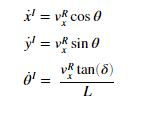       

La diferencia notoria entre estas dos ecuaciones radica en la presencia de un angulo y de la distancia entre las ruedas en la ecuación de la velocidad angular, esta diferencia al controlar el carro se vería en el control de la dirección, ya que podria hacer movimientos menos bruscos, ademas que ya no solo dependeria de una velocidad predeterminada si no de los parametros fisicos del vehiculo. 

## **Tercer Punto**

A continuación se muestra la llamada de la clase llamada "BicycleModel", el codigo se puede encontrar en los archivos de este documento. En el caso que Vx=0 el angulo de dirección mediante InverseKinematics no se puede calcular con exactitud, en este caso devuelve un 0 de ser asi.

wheelRadius = 0.05;  % [m]
Wheelbase = 0.4; % [m]  

robot = BicycleModel(wheelRadius, Wheelbase)

robot =   BicycleModel with properties:

    WheelRadius: 0.0500
      Wheelbase: 0.4000



wr    = 2*pi; % [rad/s] 
delta = 0.8*pi;   % [rad/s]
r_xi = robot.calcForwardKinematics(wr, delta)

r_xi =     0.3142
         0
   -0.5706


[wr_test, delta_test] = robot.calcInverseKinematics(r_xi) 

wr_test = 6.2832

delta_test = -0.6283

%% Se prueba el metodo
r_xi_test = robot.calcForwardKinematics(wr_test, delta_test)

r_xi_test =     0.3142
         0
   -0.5706





%% Ejemplo2 con Vx=0
wr_2    = 0; % [rad/s] 
delta_2 = 0.1;   % [rad/s]
r_xi_2 = robot.calcForwardKinematics(wr_2, delta_2)

r_xi_2 =      0
     0
     0


[wr_test_2, delta_test_2] = robot.calcInverseKinematics(r_xi_2) 

wr_test_2 = 0

delta_test_2 = 0

%% Se prueba el metodo
r_xi_test_2 = robot.calcForwardKinematics(wr_test_2, delta_test_2)

r_xi_test_2 =      0
     0
     0


## **Cuarto Punto**

Corra la siguiente linea de codigo para abrir la implemetacion en simulink.

open('Punto4.slx');

## **Quinto Punto**

Debido a que el modelo diferencial cuenta con control mediante dos velocidades, una para cada rueda, seria mas complicado para el usuario dirigir el vehiculo, mientras que con la analizada en esta tarea, el angulo y la velocidad de las ruedas pueden ser manejadas con mayor facilidad por el usuario.